## Experiment 6 : Regularization 1

1、插入数据，并绘制点图

load("ex5Linx.dat");
load("ex5Liny.dat");

2、将x变化为对应高次项，并添加截距项

for i = 1 : 7
    for j = 1 : 5
    X(i, j) = power(ex5Linx(i), j);
    end
end
x = [ones(7, 1), X];

3、定义特征矩阵spe

spe = zeros(6, 6);
for  i = 2: 6
    spe(i, i) = 1;
end

4、计算θ值(λ = 0，λ = 1，λ = 10)，并分别绘制图像

lamada = 10;
theta = inv((x'*x + lamada*spe))*x'*ex5Liny

theta =     0.5205
   -0.1825
    0.0606
   -0.1482
    0.0743
   -0.1280


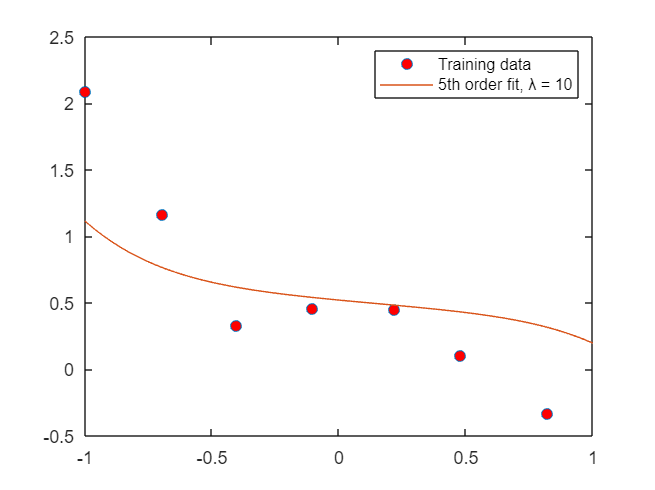

plot(ex5Linx, ex5Liny, 'o','MarkerFaceColor', 'red');
hold on
plotx = linspace(-1,1,300);
for i = 1:300
    ploty(i) = theta(1);
    for j = 2:6
    ploty(i) = ploty(i) + theta(j)*power(plotx(i), j-1);
    end
end
plot(plotx, ploty);
legend("Training data","5th order fit, λ = 10");

5、得到结果如下：